# 使用示例

功能包含两部分：求解+化简。

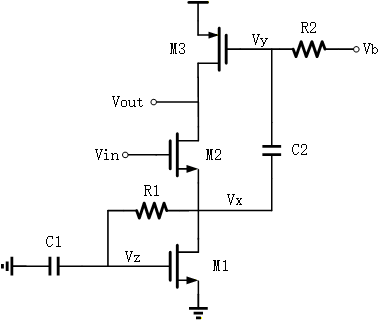

以上述电路为例，计算Vin到Vout的电压增益，以及Vout看进去的输出阻抗。为了计算输出阻抗，添加了一个测试电流源到vout节点。

这里设置电路拓扑结构输入，以及所有参数的符号定义，注意定义s。

求解使用节点电压法实现，最终得到的是一个(N+M-1)*1的向量x，包含了所有节点的电压值和所有独立电压源的电流。

节点可以使用任意的命名，使用node_map映射到实际的矩阵索引上。

circuit = struct();
syms s vin vout itest R1 R2 ro1 ro2 ro3 gm1 gm2 gm3 C1 C2;
circuit.elements = {
    % 类型, 名称, 节点+, 节点-, 值, (控制节点+, 控制节点-)
    struct('type', 'V', 'name', 'Vin', 'nodes', {{'vin', 'gnd'}}, 'value', vin),
    struct('type', 'R', 'name', 'R1', 'nodes', {{'vx', 'vz'}}, 'value', R1),
    struct('type', 'R', 'name', 'R2', 'nodes', {{'vy', 'gnd'}}, 'value', R2),
    struct('type', 'C', 'name', 'C1', 'nodes', {{'vz', 'gnd'}}, 'value', C1),
    struct('type', 'C', 'name', 'C2', 'nodes', {{'vy', 'vx'}}, 'value', C2),
    struct('type', 'MOS', 'name', 'M1', 'nodes', {{'vz', 'vx', 'gnd'}}, 'gm_value', gm1, 'ro_value', ro1),
    struct('type', 'MOS', 'name', 'M2', 'nodes', {{'vin', 'vout', 'vx'}}, 'gm_value', gm2, 'ro_value', ro2),
    struct('type', 'MOS', 'name', 'M3', 'nodes', {{'vy', 'vout', 'gnd'}}, 'gm_value', gm3, 'ro_value', ro3),
    struct('type', 'I', 'name', 'Itest', 'nodes', {{'gnd', 'vout'}}, 'value', itest) %测试电流源用以计算输出阻抗
};
% 2. 生成MNA矩阵
[A, x, z, node_map, extra_info] = generate_mna(circuit,s,'gnd');

总变量数: 6 (节点电压: 5, 额外变量: 1)
MNA矩阵生成完成！
A矩阵大小: 6 x 6, 非零元素: 15
x向量长度: 6
z向量长度: 6



show_result(A, x, z, node_map,extra_info);


=== 电路信息 ===
节点映射:
  节点 vin -> 变量 1
  节点 vout -> 变量 5
  节点 vx -> 变量 2
  节点 vy -> 变量 4
  节点 vz -> 变量 3

额外变量:
  Vin -> 变量 6

=== 矩阵信息 ===
A矩阵:


$$ans = \left(\begin{array}{cccccc} 0 & 0 & 0 & 0 & 0 & 1\\ -{\mathrm{gm}}_{2} & {\mathrm{gm}}_{2}+C_{2}\,s+\frac{1}{R_{1}}+\frac{1}{{\mathrm{ro}}_{1}}+\frac{1}{{\mathrm{ro}}_{2}} & {\mathrm{gm}}_{1}-\frac{1}{R_{1}} & -C_{2}\,s & -\frac{1}{{\mathrm{ro}}_{2}} & 0\\ 0 & -\frac{1}{R_{1}} & C_{1}\,s+\frac{1}{R_{1}} & 0 & 0 & 0\\ 0 & -C_{2}\,s & 0 & C_{2}\,s+\frac{1}{R_{2}} & 0 & 0\\ {\mathrm{gm}}_{2} & -{\mathrm{gm}}_{2}-\frac{1}{{\mathrm{ro}}_{2}} & 0 & {\mathrm{gm}}_{3} & \frac{1}{{\mathrm{ro}}_{2}}+\frac{1}{{\mathrm{ro}}_{3}} & 0\\ 1 & 0 & 0 & 0 & 0 & 0 \end{array}\right)$$

z向量:


$$ans = \left(\begin{array}{c} 0\\ 0\\ 0\\ 0\\ \mathrm{itest}\\ \mathrm{vin} \end{array}\right)$$

变量标签:
  x(1) = V(vin)
  x(2) = V(vx)
  x(3) = V(vz)
  x(4) = V(vy)
  x(5) = V(vout)
  x(6) = I(Vin)



fprintf('\n解向量 x = A\\z:\n');


解向量 x = A\z:


x

#### 以上就完成了电路的求解。然后计算增益和输出阻抗，并化简到一阶项。

计算增益的方法是直接计算Vout/vin。节点的名字和实际索引做了node_map，需要映射一遍得到实际索引。

因为式子很长，这里示例只关心电路的DC增益，即式子在s->0时的情况。注意把itest置0。

vout_idx = node_map('vout');
vin_idx = node_map('vin');
gain = subs(x(vout_idx)/x(vin_idx),itest,0)

gain_dc = simplify(limit(gain,s,0))

$$gain\_dc = -\frac{{\mathrm{gm}}_{2}\,{\mathrm{ro}}_{2}\,{\mathrm{ro}}_{3}\,\left({\mathrm{gm}}_{1}\,{\mathrm{ro}}_{1}+1\right)}{{\mathrm{ro}}_{1}+{\mathrm{ro}}_{2}+{\mathrm{ro}}_{3}+{\mathrm{gm}}_{1}\,{\mathrm{ro}}_{1}\,{\mathrm{ro}}_{2}+{\mathrm{gm}}_{1}\,{\mathrm{ro}}_{1}\,{\mathrm{ro}}_{3}+{\mathrm{gm}}_{2}\,{\mathrm{ro}}_{1}\,{\mathrm{ro}}_{2}}$$

# 基于阶数的公式化简

这个式子还是太复杂，我们只关心一阶的情况。因此这里使用另一个功能：基于阶数的公式化简。

自定义一个变量集合L（如下面的large_var），对多项式的某一项，其L阶数定义为：所有L的元素的指数的集合。

可以注意到（注意力并不惊人），gmro>>1。因此选择gm作为这个集合，simplify_by_degree函数只保留gm阶数最高的那些项。也可以保留最高和次高的项，使用第三个参数设置。

第二个参数可选项为'large'或者'small’，即如果有小量，可以反过来保留L阶数较低的项。

large_var = [gm1,gm2,gm3];
gain_dc_simplify = simplify_by_degree_main(gain_dc,'large',1,large_var)

$$gain\_dc\_simplify = -\frac{{\mathrm{gm}}_{1}\,{\mathrm{gm}}_{2}\,{\mathrm{ro}}_{2}\,{\mathrm{ro}}_{3}}{{\mathrm{gm}}_{1}\,{\mathrm{ro}}_{2}+{\mathrm{gm}}_{1}\,{\mathrm{ro}}_{3}+{\mathrm{gm}}_{2}\,{\mathrm{ro}}_{2}}$$

输出阻抗的情况同理。把输入置0，计算Vout/I_vout。

zout = simplify(subs(x(vout_idx)/itest,vin,0));
zout_dc = limit(zout,s,0)

$$zout\_dc = \frac{{\mathrm{ro}}_{3}\,\left({\mathrm{ro}}_{1}+{\mathrm{ro}}_{2}+{\mathrm{gm}}_{1}\,{\mathrm{ro}}_{1}\,{\mathrm{ro}}_{2}+{\mathrm{gm}}_{2}\,{\mathrm{ro}}_{1}\,{\mathrm{ro}}_{2}\right)}{{\mathrm{ro}}_{1}+{\mathrm{ro}}_{2}+{\mathrm{ro}}_{3}+{\mathrm{gm}}_{1}\,{\mathrm{ro}}_{1}\,{\mathrm{ro}}_{2}+{\mathrm{gm}}_{1}\,{\mathrm{ro}}_{1}\,{\mathrm{ro}}_{3}+{\mathrm{gm}}_{2}\,{\mathrm{ro}}_{1}\,{\mathrm{ro}}_{2}}$$

使用同样的方法，注意一下，有

zout_dc_simplify = simplify_by_degree_main(zout_dc,'large',1,large_var)

$$zout\_dc\_simplify = \frac{{\mathrm{ro}}_{2}\,{\mathrm{ro}}_{3}\,\left({\mathrm{gm}}_{1}+{\mathrm{gm}}_{2}\right)}{{\mathrm{gm}}_{1}\,{\mathrm{ro}}_{2}+{\mathrm{gm}}_{1}\,{\mathrm{ro}}_{3}+{\mathrm{gm}}_{2}\,{\mathrm{ro}}_{2}}$$